## Audio Features of Extreme Metal

Import songs

fs = 44100;
[black_metal1, fs1] = audioread('..\RawTracks\Darkthrone.mp3', [10*fs 30*fs]);
[black_metal2, fs2] = audioread('..\RawTracks\Emperor.mp3', [10*fs 30*fs]);
[black_metal3, fs3] = audioread('..\RawTracks\Mayhem.mp3', [10*fs 30*fs]);
[death_metal1, fs4] = audioread('..\RawTracks\Death.mp3', [10*fs 30*fs]);
[death_metal2, fs5] = audioread('..\RawTracks\MorbidAngel.mp3', [10*fs 30*fs]);
[death_metal3, fs6] = audioread('..\RawTracks\AtTheGates.mp3', [10*fs 30*fs]);
[alternative, fs7] = audioread('..\RawTracks\Radiohead.mp3', [10*fs 30*fs]);
sigLabels = {'Black1', 'Black2', 'Black3', 'Death1', 'Death2', 'Death3', 'Alternative'};
signalSet{1} = 0.5*(black_metal1(:,1)+black_metal1(:,2)); % convert stereo to mono
signalSet{2} = 0.5*(black_metal2(:,1)+black_metal2(:,2)); % convert stereo to mono
signalSet{3} = 0.5*(black_metal3(:,1)+black_metal3(:,2)); % convert stereo to mono
signalSet{4} = 0.5*(death_metal1(:,1)+death_metal1(:,2)); % convert stereo to mono
signalSet{5} = 0.5*(death_metal2(:,1)+death_metal2(:,2)); % convert stereo to mono
signalSet{6} = 0.5*(death_metal3(:,1)+death_metal3(:,2)); % convert stereo to mono
signalSet{7} = 0.5*(alternative(:,1)+alternative(:,2)); % convert stereo to mono

Check audio sections

%for I = 1 : length(signalSet) 
%    soundsc(signalSet{I}, fs)
%    pause(22)
%end

Calculate spectral roll-off

Mean spectral roll-off is 0.15646


Peak spectral roll-off is 0.19683


Minimum spectral roll-off for is 0.076923


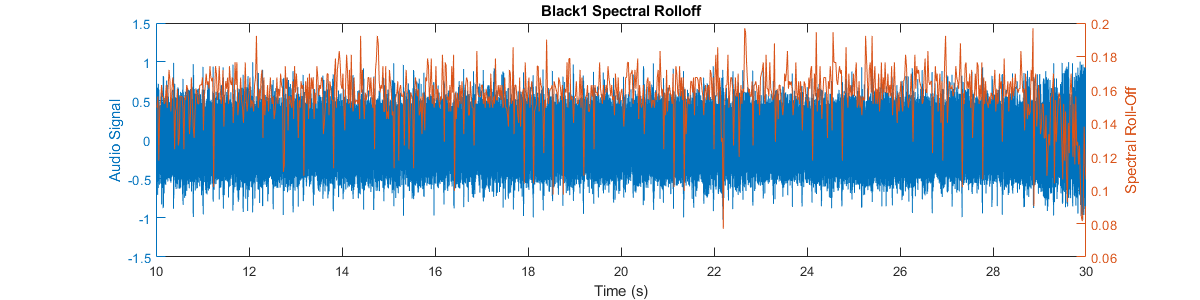

Mean spectral roll-off is 0.15628


Peak spectral roll-off is 0.26697


Minimum spectral roll-off for is 0.011312


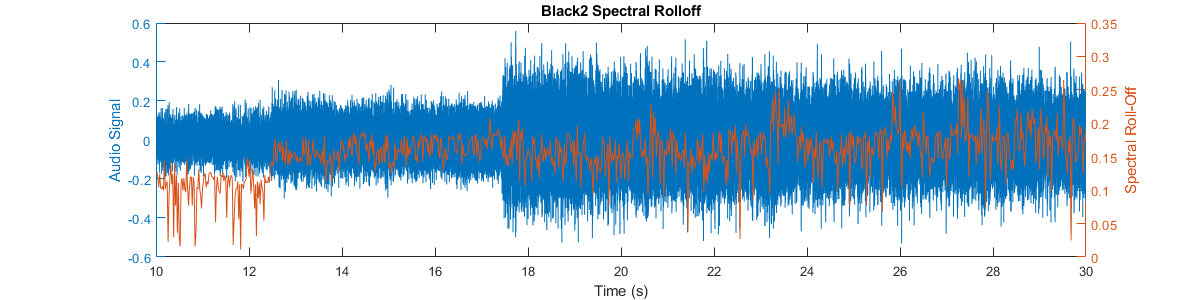

Mean spectral roll-off is 0.15907


Peak spectral roll-off is 0.28054


Minimum spectral roll-off for is 0.011312


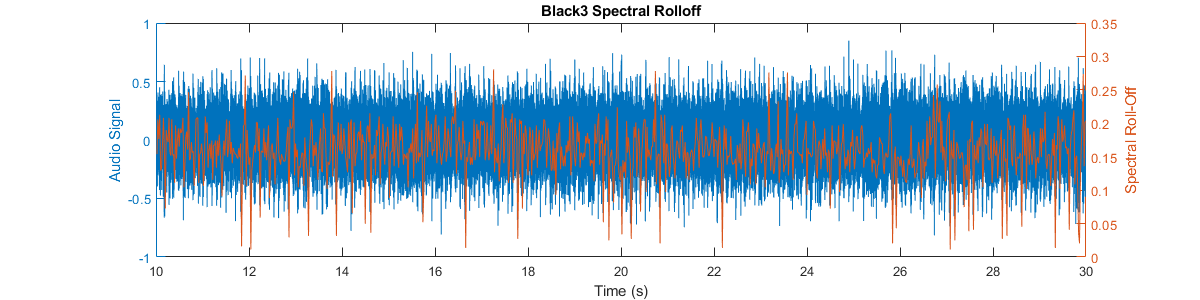

Mean spectral roll-off is 0.15207


Peak spectral roll-off is 0.33484


Minimum spectral roll-off for is 0.0045249


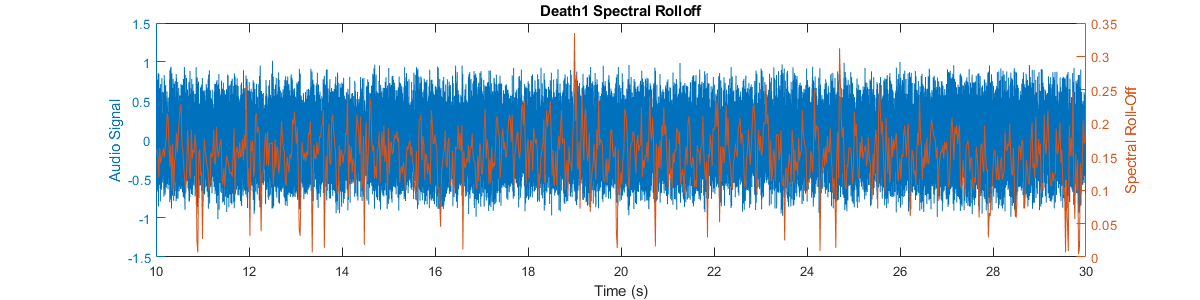

Mean spectral roll-off is 0.17169


Peak spectral roll-off is 0.32353


Minimum spectral roll-off for is 0.0090498


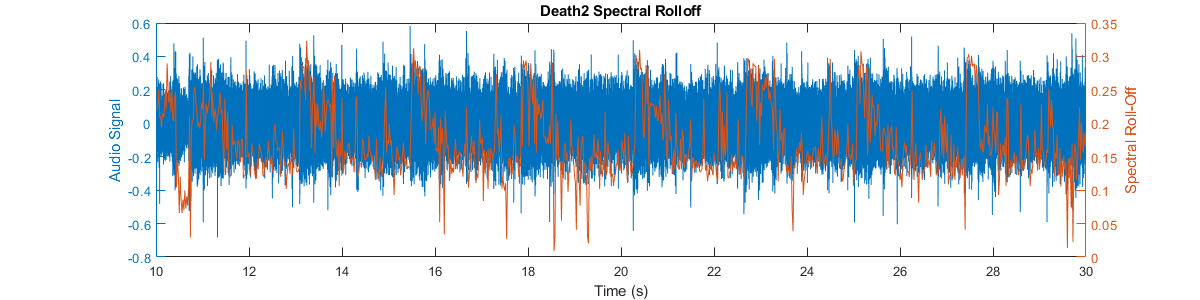

Mean spectral roll-off is 0.18261


Peak spectral roll-off is 0.46833


Minimum spectral roll-off for is 0.0090498


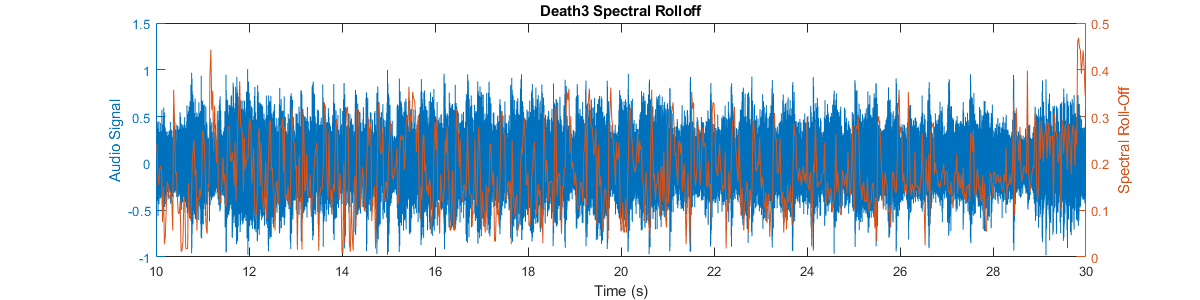

Mean spectral roll-off is 0.11078


Peak spectral roll-off is 0.62896


Minimum spectral roll-off for is 0.0045249


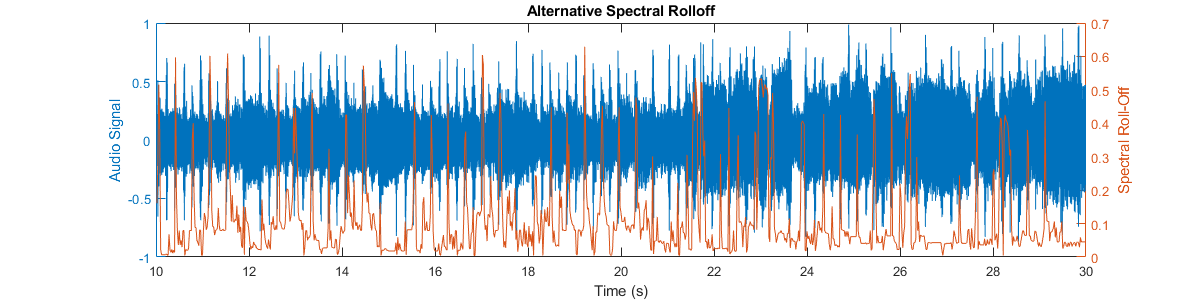

close all;
mean_rolloff = zeros(length(signalSet),1);
peak_rolloff = zeros(length(signalSet),1);
min_rolloff = zeros(length(signalSet),1);
F_sig = zeros(length(signalSet),1000);
F_entropy = zeros(length(signalSet),1000);
for I = 1 : length(signalSet)
    figure('Renderer', 'painters', 'Position', [10 10 1200 300])
    Features = stFeatureExtraction(signalSet{I}, fs, 0.02, 0.02) ;
    F = Features(8,:);
    F_sig(I,:) = Features(8,:);
    F_entropy(I,:) = Features(7,:);
    tAxis = 10+(0:length(signalSet{I})-1)/fs;
    tFeat = 10+(0.02:0.02:length(signalSet{I})/fs);
    yyaxis left
    plot(tAxis, signalSet{I})
    ylabel('Audio Signal')
    hold on ;
    yyaxis right
    plot(tFeat, F) ;
    ylabel('Spectral Roll-Off')
    xlabel('Time (s)')
    title([sigLabels{I}, ' Spectral Rolloff'])
    mean_rolloff(I) = mean(F);
    peak_rolloff(I) = max(F);
    min_rolloff(I) = min(F);
    disp(['Mean spectral roll-off is ', num2str(mean_rolloff(I))])
    disp(['Peak spectral roll-off is ', num2str(peak_rolloff(I))])
    disp(['Minimum spectral roll-off for is ', num2str(min_rolloff(I))])
    hold off;
end

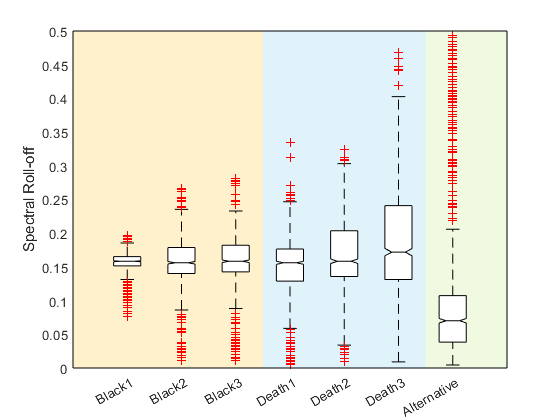

figure1 = figure;
axes1 = axes('Parent', figure1);

ylabel('Spectral Roll-off')
hold on;
rectangle('Parent', axes1, 'position', [0 -1 3.5 2], 'FaceColor', [1 0.945 0.8 0.7], 'edgecolor', 'none')
rectangle('Parent', axes1, 'position', [3.5 -1 3 2], 'FaceColor', [0.878 0.952 0.980 0.7], 'edgecolor', 'none')
rectangle('Parent', axes1, 'position', [6.5 -1 1.5 2], 'FaceColor', [0.937 0.980 0.878 0.7], 'edgecolor', 'none')
boxplot(F_sig','Notch','on','Labels', sigLabels)

h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),'w');
end
h2 = findobj(gcf, 'type', 'line', 'Tag', 'Median');
for j=1:length(h2)
    patch(get(h2(j),'XData'),get(h2(j),'YData'),'r');
end

rectangle('Parent', axes1, 'position', [0 0 8 0.5], 'FaceColor', 'none', 'edgecolor', 'k', 'linewidth', 0.5)
ylim([0 0.5])

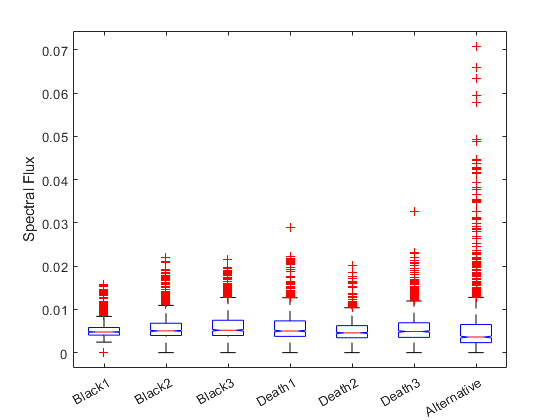

figure
boxplot(F_entropy', 'Notch', 'on', 'Labels', sigLabels)
ylabel('Spectral Flux')